data = importdata("Assignment_Data_SC42145_2022.mat");
FWT=data.FWT;
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



Wi1=((s/(16*pi))+0.3)/((s/(64*pi))+1)

Wi1 =
 
    201.1 s + 3032
  ------------------
  50.27 s + 1.011e04
 
Continuous-time transfer function.



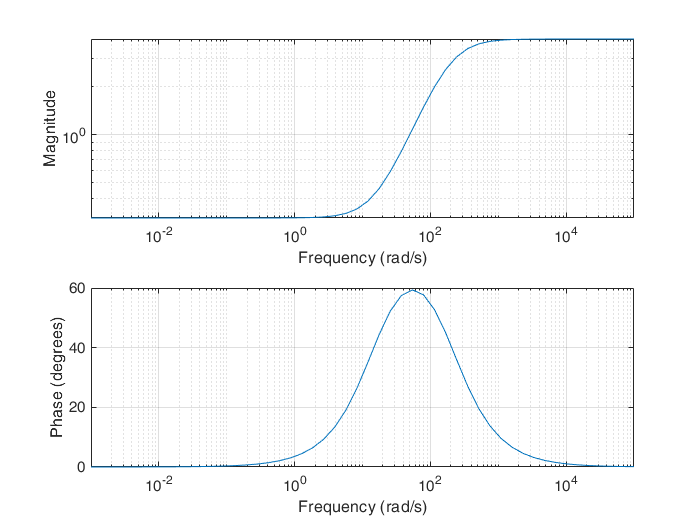

Wi2=((s/(16*pi))+0.3)/((s/(64*pi))+1);
Wi=[Wi1 0;0 Wi2];

Wo1=((0.05*s)+0.02)/((0.01*s)+1);
Wo2=((0.05*s)+0.02)/((0.01*s)+1);
Wo=[Wo1 0;0 Wo2];



Wia = [1/(64*pi) 1];
Wib = [1/(16*pi) 0.3];
wi = logspace(-3,5);

figure
freqs(Wib,Wia,wi)

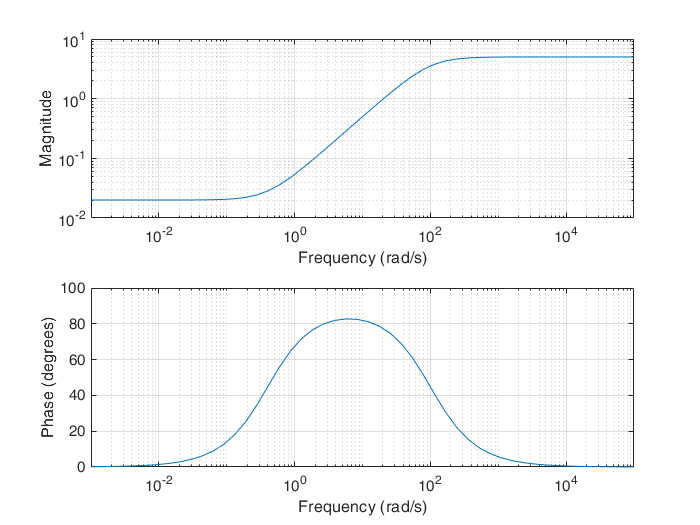



Woa = [0.01 1];
Wob = [0.05 0.02];
wo = logspace(-3,5);

figure
freqs(Wob,Woa,wo)


H = ultidyn("H",2)

H =   Uncertain LTI dynamics "H" with 2 outputs, 2 inputs, and gain less than 1.



DeltaInput=Wo*H*Wi

DeltaInput =

  Uncertain continuous-time state-space model with 2 outputs, 2 inputs, 4 states.
  The model uncertainty consists of the following blocks:
    H: Uncertain 2x2 LTI, peak gain = 1, 1 occurrences

Type "DeltaInput.NominalValue" to see the nominal value, "get(DeltaInput)" to see all properties, and "DeltaInput.Uncertainty" to interact with the uncertain elements.



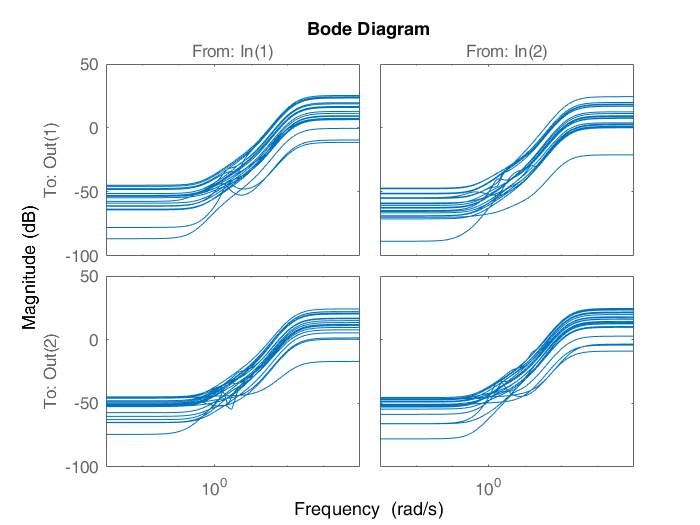

figure()
bodemag(DeltaInput)

S = svd(DeltaInput.A)

S =   201.0619
  201.0619
  100.0000
  100.0000


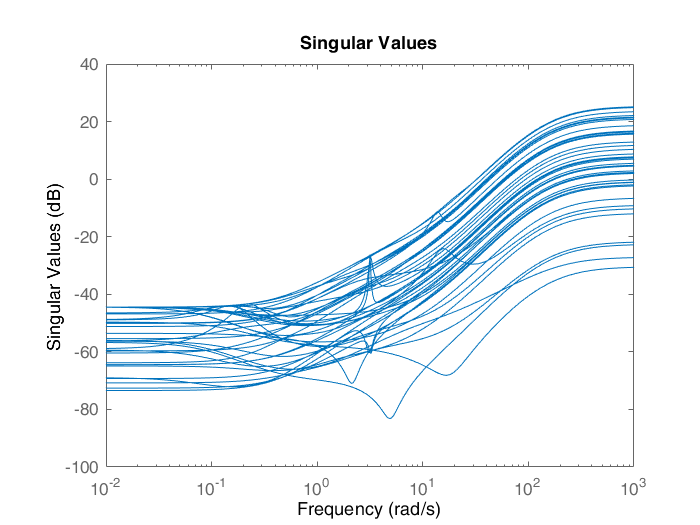

figure()
sigma(DeltaInput)

wB1=0.3*2*pi; % desired closed-loop bandwidth
wB2=0.2; % desired closed-loop bandwidth
A=1/10000; % desired disturbance attenuation inside bandwidth
M=3; % desired bound on hinfnorm(S)
Wp11=tf([1/M wB1],[1 wB1*A]);
Wp=[Wp11 0; 0 wB2]; %

% Control weights
Wu22 =(5e-3*s^2+7e-4*s+5e-5)/(s^2+14e-4*s+1e-6);
Wu=[0.01 0; 0 Wu22]; % Control weight
Wt=[]; % Empty weight

G=tf(FWT(1:2,1:2));

%get controller from first part
Plant=augw(G,Wp,Wu,[]); 
P1=minreal(Plant) 

5 states removed.

P1 =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1     0.2542    0.01037     0.0467     -1.183     0.7419     0.2764    0.05737     0.0809
   x2      0.406   -0.04018   -0.01065     0.1624    -0.4212    0.02059   -0.03215   -0.01831
   x3  -0.009303     0.2577   -0.01156    -0.1082     0.1401   -0.03529    0.05568  -0.002812
   x4     0.4283    -0.3171     0.1516    -0.1668       -3.6     -1.245    -0.4001    -0.3966
   x5     -1.248     -0.118    -0.3571      2.404    -0.3779    -0.3885   -0.02829    -0.1212
   x6    -0.6088   -0.04575    -0.1488     0.4175     -0.187    -0.2818   -0.02759   -0.08366
   x7    -0.1719   -0.04049    -0.0747      0.201    -0.2057    -0.1278   -0.02487   -0.04576
   x8     0.2264    0.03512    0.08107     0.2642    0.05619     0.1472    0.01703    0.04939
 
  B = 
                ?           ?  Beta (deg)  tau_e (Nm)
   x1     0.05657           0    -0.07384     0.01122
   x

[K,CL,GAM,INFO] = hinfsyn(P1,2,2); %K is controller

P=[zeros(2) zeros(2) zeros(2) Wi;Wo*G zeros(2) zeros(2) Wo*G;Wp*G Wp Wp Wp*G;zeros(2) zeros(2) zeros(2) Wu; -G -1*eye(2) -1*eye(2) -G]

P =
 
  From input "Beta (deg)" to output...
   1:  0
 
   2:  0
 
       -0.003994 s^5 - 0.001763 s^4 - 0.04345 s^3 - 0.01703 s^2 - 0.001599 s - 0.0006916
   3:  ---------------------------------------------------------------------------------
         0.01 s^6 + 1.006 s^5 + 0.7077 s^4 + 11.02 s^3 + 4.715 s^2 + 0.5439 s + 0.1827
 
            -0.002437 s^4 - 0.002715 s^3 - 0.004445 s^2 - 0.004099 s - 0.00104
   4:  -----------------------------------------------------------------------------
       0.01 s^6 + 1.006 s^5 + 0.7077 s^4 + 11.02 s^3 + 4.715 s^2 + 0.5439 s + 0.1827
 
       -0.02663 s^5 - 0.1517 s^4 - 0.2955 s^3 - 1.633 s^2 + 0.0007121 s - 0.06518
   5:  ---------------------------------------------------------------------------
       s^6 + 0.5981 s^5 + 10.98 s^4 + 4.711 s^3 + 0.543 s^2 + 0.1828 s + 3.444e-05
 
            -0.009748 s^3 - 0.006961 s^2 - 0.01499 s - 0.0104
   6:  ------------------------------------------------------------
       s^5 + 0.5979 s^4 + 10.98 s^3

P=minreal(P)

P =
 
  From input "Beta (deg)" to output...
   1:  0
 
   2:  0
 
       -0.3994 s^5 - 0.1763 s^4 - 4.345 s^3 - 1.703 s^2 - 0.1599 s - 0.06916
   3:  ---------------------------------------------------------------------
       s^6 + 100.6 s^5 + 70.77 s^4 + 1102 s^3 + 471.5 s^2 + 54.39 s + 18.27
 
             -0.2437 s^4 - 0.2715 s^3 - 0.4445 s^2 - 0.4099 s - 0.104
   4:  --------------------------------------------------------------------
       s^6 + 100.6 s^5 + 70.77 s^4 + 1102 s^3 + 471.5 s^2 + 54.39 s + 18.27
 
       -0.02663 s^5 - 0.1517 s^4 - 0.2955 s^3 - 1.633 s^2 + 0.0007121 s - 0.06518
   5:  ---------------------------------------------------------------------------
       s^6 + 0.5981 s^5 + 10.98 s^4 + 4.711 s^3 + 0.543 s^2 + 0.1828 s + 3.444e-05
 
            -0.009748 s^3 - 0.006961 s^2 - 0.01499 s - 0.0104
   6:  ------------------------------------------------------------
       s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
   7:  0
 
   8:  0
 
     

Pl=ss(P)

Pl =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7
   x1       -201.1           0           0           0           0           0           0
   x2            0      -201.1           0           0           0           0           0
   x3            0           0           0           0           0           0           0
   x4            0           0         0.5           0           0           0           0
   x5            0           0           0         0.5           0           0           0
   x6            0           0           0           0           2           0           0
   x7            0           0           0           0           0          16           0
   x8            0           0           0           0           0           0           8
   x9            0           0           0           0           0           0           0
   x10           0           0           0           0           0          

Pss=minreal(Pl)

45 states removed.

Pss =
 
  A = 
               x1         x2         x3         x4         x5         x6         x7         x8
   x1      -64.03      49.06     -13.98      15.64     -6.205     -20.34   -0.04011      5.867
   x2       49.03     -81.86      1.088     0.3899    -0.4815     0.1944  0.0007464   -0.05043
   x3      -11.74      2.359     -4.606      4.345     -1.932     -7.322   -0.01491      2.081
   x4        13.7    -0.8371      4.952     -5.973      2.357       8.08    0.01568     -2.289
   x5      -5.232     0.3455     -1.954      1.889    -0.7207     -3.379  -0.003944     0.6793
   x6       -18.6      1.195     -6.934      7.632     -2.816     -11.31    0.04971      3.216
   x7    -0.03739   0.002396   -0.01394    0.01534  -0.005976    0.04968     -201.1      -1.14
   x8       5.383    -0.3449      2.007     -2.209     0.8605      3.261      -1.14     -8.709
   x9      -1.555    0.09963    -0.5797     0.6382    -0.2486    -0.9421  -0.001857     -26.53
   x10     -3.1

N=lft(P,K)

N =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7
   x1       -201.1           0           0           0           0           0           0
   x2            0      -201.1           0           0           0           0           0
   x3            0           0           0           0           0           0           0
   x4            0           0         0.5           0           0           0           0
   x5            0           0           0         0.5           0           0           0
   x6            0           0           0           0           2           0           0
   x7            0           0           0           0           0          16           0
   x8            0           0           0           0           0           0           8
   x9            0           0           0           0           0           0           0
   x10           0           0           0           0           0           

N=minreal(N)

44 states removed.

N =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7
   x1        -1232        -448       790.6       -1575       -9419      -337.9        -4.4
   x2        231.8       23.22        -104       296.2        1772        72.2       11.62
   x3         1273         517      -852.9        1640        9817       356.2      -15.31
   x4       -656.9      -241.9       422.6      -843.6       -5048      -185.9       4.485
   x5        525.4       194.6        -338       674.7        4037       148.3      -3.206
   x6         3809        1414       -2453        4889   2.926e+04        1074      -22.23
   x7        -6122       -2252        3924       -7860  -4.705e+04       -1734       37.08
   x8       -109.9      -31.92       62.99      -141.7        -849      -33.96       1.594
   x9        784.9       289.6      -503.9        1007        6031         222       -4.74
   x10      -159.6      -58.28       101.9      -204.9   